# 3-1-a:

clc;
clear;
close all;

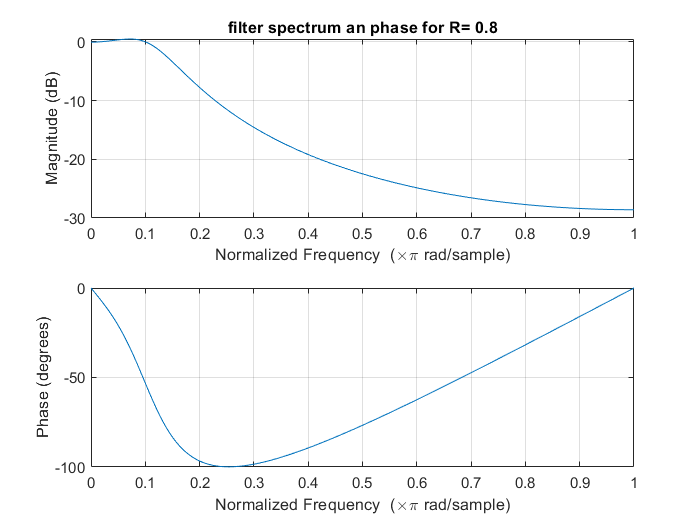



f0 = 500; % Hz
fs = 10000; % Hz
w  = 2 * pi * f0 / fs;

R = 0.80;
G = (1 - R) * (1 - 2*R*cos(2*w) + R^2)^0.5;
b = G;
a = [1, -2*R*cos(w), R^2];
figure(1)
freqz(b, a, linspace(0, pi, 500));
title("filter spectrum an phase for R= 0.8")

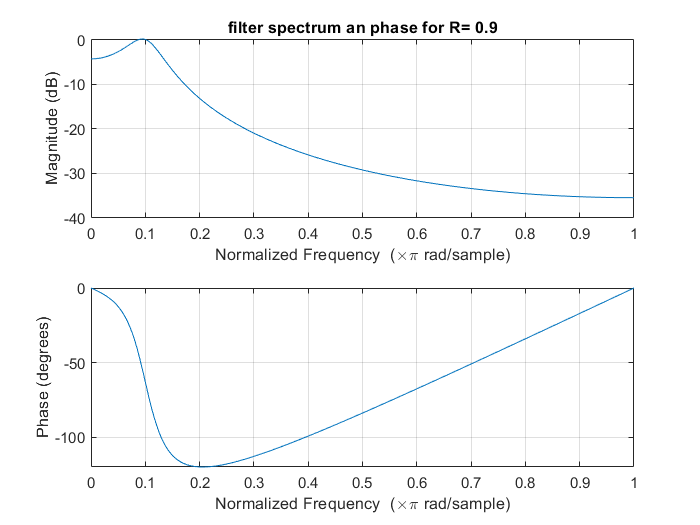


R = 0.90;
G = (1 - R) * (1 - 2*R*cos(2*w) + R^2)^0.5;
b = G;
a = [1, -2*R*cos(w), R^2];
figure(2)
freqz(b, a, linspace(0, pi, 500));
title("filter spectrum an phase for R= 0.9")

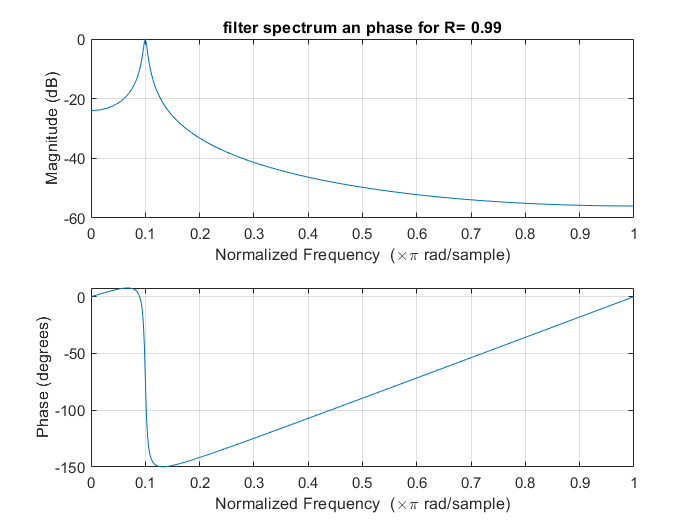


R = 0.99;
G = (1 - R) * (1 - 2*R*cos(2*w) + R^2)^0.5;
b = G;
a = [1, -2*R*cos(w), R^2];
figure(3)
freqz(b, a, linspace(0, pi, 500));
title("filter spectrum an phase for R= 0.99")

## 3-1-b:

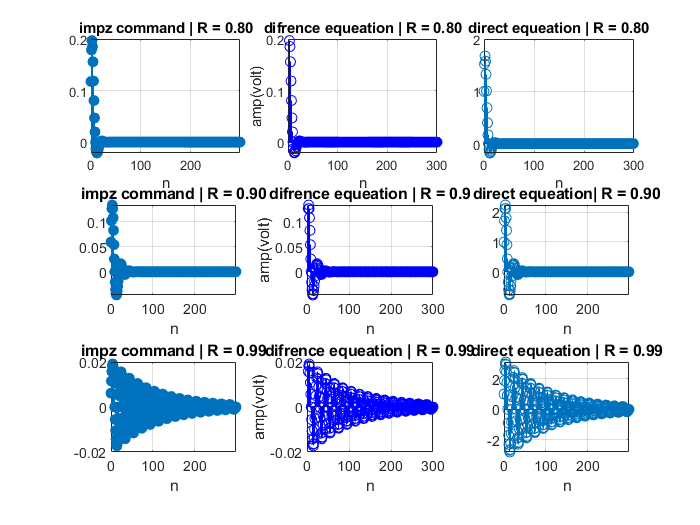

clc;clear;close all;
f0 = 500; % Hz
fs = 10000; % Hz
w  = 2 * pi * f0 / fs;
N = 300;
n = 0:N-1;
y = zeros(1,N);

R = 0.80;
G = (1 - R) * (1 - 2*R*cos(2*w) + R^2)^0.5;
b = G;
a = [1, -2*R*cos(w), R^2];
y(1) = G;
y(2) = -a(2)*y(1);
for kk = 3:N
    y(kk) = -a(2)*y(kk-1) - a(3)*y(kk-2);
    hold on;
    subplot(3,3,2);
    stem(kk,y(kk),'b');
    grid on;
    xlabel('n');
    ylabel('amp(volt)');
    title('difrence equeation | R = 0.80');
end
h_n = (G/(sin(w))).*R.^n.*sin(w.*(n + 1));

%%figure(4)
subplot(3,3,3);
stem(n, h_n/G);
grid on;
xlabel('n');
ylabel('');
title('direct equeation | R = 0.80');

subplot(3,3,1);
impz(h_n)
grid on;
xlabel('n');
ylabel('');
title('impz command | R = 0.80');


R = 0.90;
G = (1 - R) * (1 - 2*R*cos(2*w) + R^2)^0.5;
b = G;
a = [1, -2*R*cos(w), R^2];
y(1) = G;
y(2) = -a(2)*y(1);
for kk = 3:N
    y(kk) = -a(2)*y(kk-1) - a(3)*y(kk-2);
    hold on;
    subplot(3,3,5);
    stem(kk,y(kk),'b');
    grid on;
    xlabel('n');
    ylabel('amp(volt)');
    title('difrence equeation | R = 0.9');
end
h_n = (G/(sin(w))).*R.^n.*sin(w.*(n + 1));

%%figure(5)
subplot(3,3,6);
stem(n, h_n/G);
grid on;
xlabel('n');
ylabel('');
title('direct equeation| R = 0.90');
subplot(3,3,4);
impz(h_n)
grid on;
xlabel('n');
ylabel('');
title('impz command | R = 0.90');

R = 0.99;
G = (1 - R) * (1 - 2*R*cos(2*w) + R^2)^0.5;
b = G;
a = [1, -2*R*cos(w), R^2];
y(1) = G;
y(2) = -a(2)*y(1);
for kk = 3:N
    y(kk) = -a(2)*y(kk-1) - a(3)*y(kk-2);
    hold on;
    subplot(3,3,8);
    stem(kk,y(kk),'b');
    grid on;
    xlabel('n');
    ylabel('amp(volt)');
    title('difrence equeation | R = 0.99');
end
h_n = (G/(sin(w))).*R.^n.*sin(w.*(n + 1));

%%figure(6)
subplot(3,3,9);
stem(n, h_n/G);
grid on;
xlabel('n');
ylabel('');
title('direct equeation | R = 0.99');
subplot(3,3,7);
impz(h_n)
grid on;
xlabel('n');
ylabel('');
title('impz command | R = 0.99');

## 3-1-c:

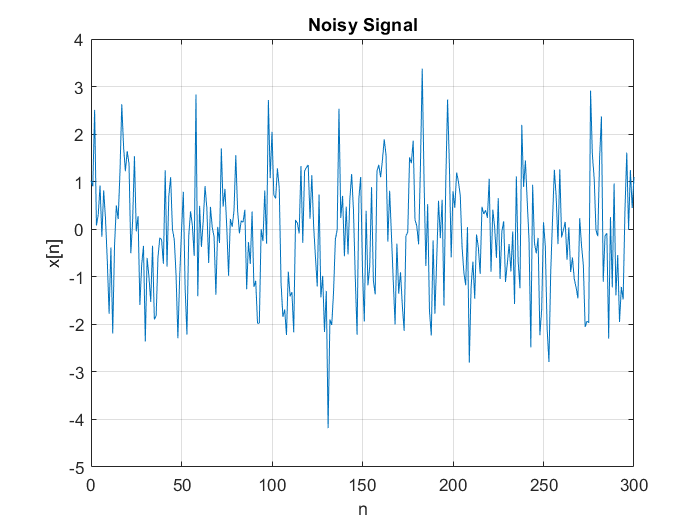

clear;
clc;
close all;
f0 = 500; % Hz
fs = 10000; % Hz
w  = 2 * pi * f0 / fs;
R = [0.80, 0.90, 0.99];

N = 300;
n  = 0:1:N;
s  = cos (w*n);
v  = randn(1,length(n));
x  = s + v;

figure(7);
plot(n, x);
grid on;
xlabel('n');
ylabel('x[n]');
title('Noisy Signal');

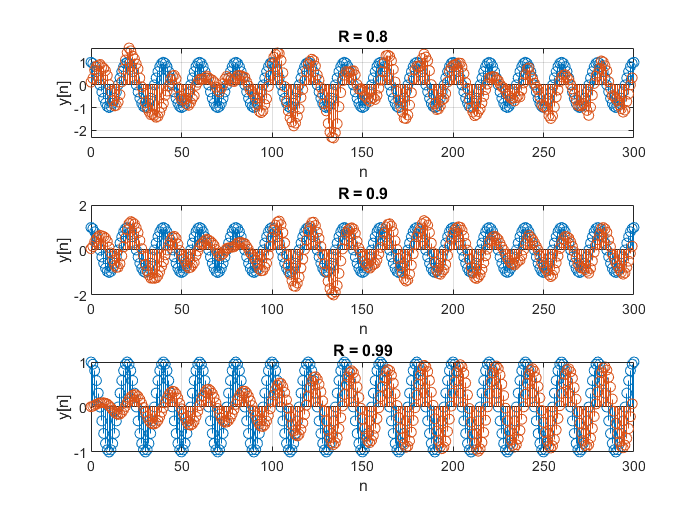


for ll = 1:length(R)
    G = (1 - R(ll)) * (1 - 2*R(ll)*cos(2*w) + R(ll)^2)^0.5;
    b = G;
    a = [1, -2*R(ll)*cos(w), R(ll)^2];
    y = zeros(1,N);
    for mm = 1:N
        if (mm == 1)
            y(mm) = G*x(mm) ;
            w1 = y(1) ;
        elseif(mm == 2)
            y(mm) = -a(2)*w1 + G*x(mm) ;
            w2 = w1;
            w1 = y(2) ;
        else
            y(mm) = -a(2)*w1 - a(3)*w2 + G*x(mm) ;
            w2 = w1;
            w1 = y(mm);
        end
    end
    figure(8)
    subplot(length(R), 1, ll);
    stem(n, s);
    hold on;
    stem(n(1:end-1), y);
    grid on;
    xlabel('n');
    ylabel('y[n]');
    title("R = " + num2str(R(ll)));
    
end

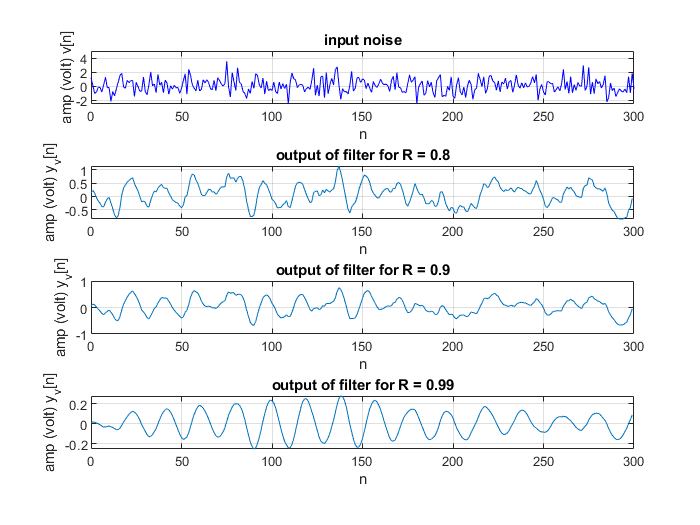

%% 3-1-d:
f0 = 500; % Hz
fs = 10000; % Hz
w  = 2 * pi * f0 / fs;
R = [0.80, 0.90, 0.99];
N = 300;
n  = 0:1:N;
s  = cos (w*n);
v  = randn(1,length(n));
x  = s + v;

for ll = 1:length(R)
    G = (1 - R(ll)) * (1 - 2*R(ll)*cos(2*w) + R(ll)^2)^0.5;
    b = G;
    a = [1, -2*R(ll)*cos(w), R(ll)^2];
    y_v = zeros(1,N);
    for mm = 1:N
        if (mm == 1)
            y_v(mm) = G*v(mm) ;
            w1 = y_v(1) ;
        elseif(mm == 2)
            y_v(mm) = -a(2)*w1 + G*v(mm) ;
            w2 = w1;
            w1 = y_v(2) ;
        else
            y_v(mm) = -a(2)*w1 - a(3)*w2 + G*v(mm) ;
            w2 = w1;
            w1 = y_v(mm);
        end
    end
    if(ll == 1)
        figure(9)
        subplot(length(R)+1, 1, ll);
        plot(n, v, 'b');
        hold on;
        grid on;
        xlabel('n');
        ylabel('amp (volt) v[n]');
        title('input noise');
    end
    figure(9)
    subplot(length(R)+1, 1, ll+1);
    plot(n(1:end-1), y_v);
    grid on;
    xlabel('n');
    ylabel('amp (volt) y_v[n]');
    title("output of filter for R = " + num2str(R(ll)));
end

## 3-1-e:

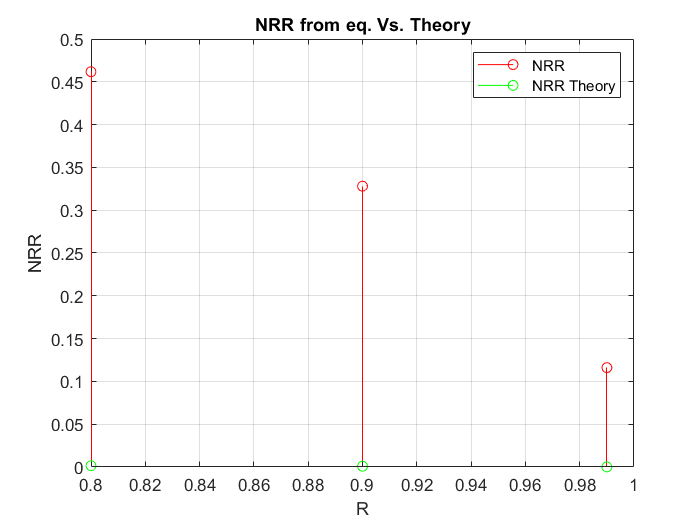

clc;
clear;close all;

f0 = 500; % Hz
fs = 10000; % Hz
w  = 2 * pi * f0 / fs;
R = [0.80, 0.90, 0.99];
N = 300;
n  = 0:1:N;
s  = cos (w*n);
v  = randn(1,length(n));
x  = s + v;
for ll = 1:length(R)
    G = (1 - R(ll)) * (1 - 2*R(ll)*cos(2*w) + R(ll)^2)^0.5;
    b = G;
    a = [1, -2*R(ll)*cos(w), R(ll)^2];
    y_v = zeros(1,N);
    for mm = 1:N
        if (mm == 1)
            y_v(mm) = G*v(mm) ;
            w1 = y_v(1) ;
        elseif(mm == 2)
            y_v(mm) = -a(2)*w1 + G*v(mm) ;
            w2 = w1;
            w1 = y_v(2) ;
        else
            y_v(mm) = -a(2)*w1 - a(3)*w2 + G*v(mm) ;
            w2 = w1;
            w1 = y_v(mm);
        end
    end
    NRR = std(y_v)/std(v);
    NRR_th = (G^2/2*sin(w)^2)*((1/(1-R(ll)^2))-((cos(2*w)-R(ll)^2)/(1-2*R(ll)^2*cos(2*w)+R(ll)^4)));
%     NRR_th = (1+R(ll)^2)/((1+R(ll))*(1+2*R(ll)*cos(w)+R(ll)^2));

    figure(10);
    stem(R(ll), NRR, 'r');
    hold on;
    stem(R(ll), NRR_th, 'g');
    grid on;
    xlabel('R');
    ylabel('NRR');
    title('NRR from eq. Vs. Theory');
    legend('NRR', 'NRR Theory');
end